
================= 稳态输出参数 =================
稳态储热温度 Ts_ss           = 362.3280 K
稳态输入热量 Qin_ss          = 38749.8580 W
稳态散热量 Qloss_ss          = 30.2143 W
净热量（应接近0）Qnet_ss     = 38719.6436 W
最后时刻温度变化率 dTs/dt    = 0.030778 K/s
稳态判定：尚未完全达到稳态 ×（可增加模拟时间）



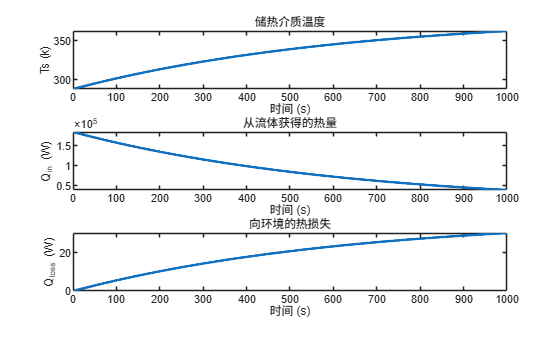

% 输入参数
Tf    = 382;      % 载热流体温度 (K)
mdot  = 0.469;    % 质量流量 (kg/s)
cp_f  = 4.2e3;    % 流体比热 (J/kg/K)
Tenv  = 288;      % 环境温度
U     = 0.01355;  % 传热系数 (W/m²·K)
A     = 30;       % 换热面积 (m²)
M     = 300;      % 储热介质量 (kg)
cp_s  = 4.2e3;    % 储热介质 cp (J/kg/K)
Ts0   = 288;      % 初始温度
t_end = 1000;     % 模拟时长 (s)

[t, Ts, Qin, Qloss] = thermal_storage_simulation_in( ...
    Tf, mdot, cp_f, Tenv, U, A, M, cp_s, Ts0, t_end);